# Exam January 11, 2019

## Exercise 1

clear
q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

syms d1 a4 L
dh = [ pi/2 0 d1 q(1);
       pi/2 0 0 q(2);
       pi/2 0 q(3) pi;
       0 a4 0 q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d_{1} & q_{1}\\ \frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 0 & q_{3} & \pi \\ 0 & a_{4} & 0 & q_{4} \end{array}\right)$$


[T Tpartial] = getTransformationMatrix(dh,'alpha')

$$T = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{4}\right) & -\cos\left(q_{2}+q_{4}\right) & 0 & d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right) \end{array}$$

Tpartial = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}



for inm=1:4
Tpartial{inm}
end

$$ans = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 1 & 0 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & a_{4}\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & a_{4}\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%Efficient Computation 4p(p)
phomvector=[0,0,0,1]';
n_p=[];
for inm=[4:-1:1]
    phomvector=simplify(Tpartial{inm}*phomvector)
    n_p=phomvector;
end

$$phomvector = \left(\begin{array}{c} a_{4}\,\cos\left(q_{4}\right)\\ a_{4}\,\sin\left(q_{4}\right)\\ 0\\ 1 \end{array}\right)$$

$$phomvector = \left(\begin{array}{c} -a_{4}\,\cos\left(q_{4}\right)\\ 0\\ q_{3}+a_{4}\,\sin\left(q_{4}\right)\\ 1 \end{array}\right)$$

$$phomvector = \left(\begin{array}{c} q_{3}\,\sin\left(q_{2}\right)-a_{4}\,\cos\left(q_{2}+q_{4}\right)\\ -a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 0\\ 1 \end{array}\right)$$

$$phomvector = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 1 \end{array}\right)$$


P = T(1:3,4)

$$P = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

q0 = [0  pi/2 L 0]

$$q0 = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & L & 0 \end{array}\right)$$

P4_0 = subs(P,q,q0)

$$P4\_0 = \left(\begin{array}{c} L\\ 0\\ d_{1}-a_{4} \end{array}\right)$$

close all
% Lengths just to test
len = 20

len = 20

len1 = 10

len1 = 10

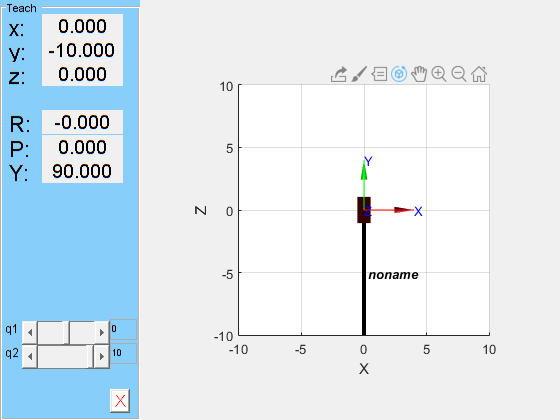

% De Luca's approach
links = [
    Revolute('a', 0, 'alpha', pi/2 ,'d', 0);
%     Revolute('a', 0, 'alpha',pi/2 ,'d', 0);
    Prismatic('qlim', [0 len1],'alpha',0*pi/2,'theta',0*pi/2);
%     Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];
c600 = SerialLink(links);
c600.teach([0*pi/2 len1],'view','x')

%c600.plot([0  pi/2 10 0],'view','x')